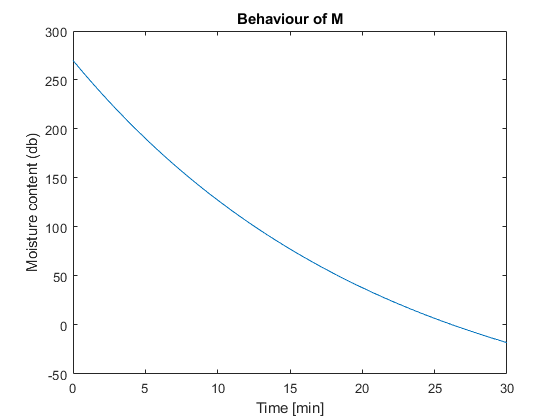

clc
close all
clear

global Ta v_in HR_in
Ta=45;
v_in=0.5;
HR_in=0.2;

x0=270; %Condición inicial del contenido de humedad
horas=30;
tiempo=horas*3600; %Tiempo en segundos
tspan = 0:100:tiempo;

[t,x]=ode23tb(@fun_Hossain,tspan,x0); 

Me=-340.573+5.787472*Ta-193.212*HR_in+238.7285*HR_in^2-22.3649*v_in+32.9541*v_in^2;
M0_Me=584.8448-5.40847*Ta+239.8359*HR_in-260.357*HR_in^2+29.1755*v_in-48.838*v_in^2;
MR=(x-Me)/(M0_Me);

figure (1)
plot(t/3600,x);
title('Behaviour of M');xlabel('Time [min]');ylabel('Moisture content (db)')

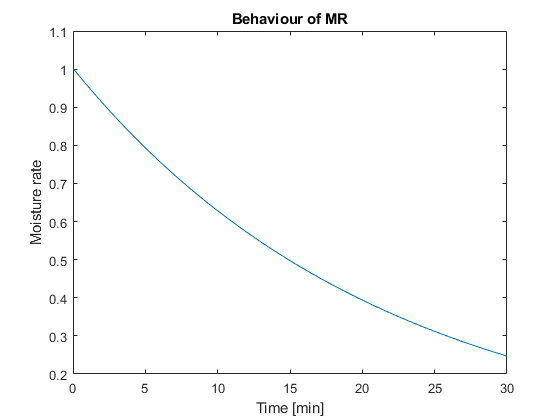

figure(2)
plot(t/3600,MR);
title('Behaviour of MR');xlabel('Time [min]');ylabel('Moisture rate')

function fx=fun_Hossain(t,x);
fx=0;
M=x(1);

global Ta v_in HR_in


k=(0.003484-0.000222*Ta+0.00000366*Ta^2-0.007085*HR_in+0.00572*HR_in^2+0.002738*v_in-0.001235*v_in^2)/60;
Me=-340.573+5.787472*Ta-193.212*HR_in+238.7285*HR_in^2-22.3649*v_in+32.9541*v_in^2;
M0_Me=584.8448-5.40847*Ta+239.8359*HR_in-260.357*HR_in^2+29.1755*v_in-48.838*v_in^2;

%fx(1)=- k * (M0_Me)*exp(-k*t);
fx(1)=-k*(M-Me);

end